clear; clc; close all;

%% ------------------------- USER INPUT -----------------------------------
% Input shaft conditions
n_in_rpm  = 1800;             % input speed [rpm]
P_in_W    = 7500;             % input power [W] (~10 hp)
dir_in    = +1;               % +1 = CW reference, -1 = CCW (arbitrary)

% Geometry units: choose ONE
use_module = true;            % true: module [mm/tooth]; false: diametral pitch [teeth/in]
if use_module
    unit_name = 'mm';         % center distance output units
else
    unit_name = 'inch';
end

% Define stages (ordered). Each row: [z_p, z_g, m_or_DP, eff, typeCode]
% typeCode: 0 = external, 1 = internal
% m_or_DP: if use_module==true -> module (mm/tooth). If false -> DP (teeth/in).
stages = [
    18, 54, 2.0, 0.98, 0 ;   % Stage 1: external, module 2.0, 98% efficient
    20, 40, 2.0, 0.97, 0 ;   % Stage 2: external
    24, 72, 2.0, 0.99, 1 ;   % Stage 3: INTERNAL (ring gear), same module
];

% (Optional) names for shafts (there are #stages+1 shafts)
shaft_names = {'Motor','Shaft 2','Shaft 3','Output'};

%% ---------------------- CALCULATION ENGINE ------------------------------
nStages = size(stages,1);
nShafts = nStages + 1;

z_p   = stages(:,1);
z_g   = stages(:,2);
mDP   = stages(:,3);
eta   = stages(:,4);
tcode = stages(:,5);   % 0 ext, 1 int

% Basic checks
assert(all(z_p>0 & z_g>0 & eta>0 & eta<=1), 'Invalid teeth or efficiencies.');
if use_module
    assert(all(mDP>0), 'Module must be > 0.');
else
    assert(all(mDP>0), 'Diametral Pitch must be > 0.');
end

% Per-stage ratio magnitude and direction multipliers
r_stage = z_p ./ z_g;                 % magnitude factor
sgn     = ones(nStages,1);
sgn(tcode==0) = -1;                   % external flips direction
sgn(tcode==1) = +1;                   % internal keeps direction

% Overall train value (nout/nin)
train_val = prod(sgn .* r_stage);

% Speeds on each shaft
n_rpm = zeros(nShafts,1);
n_rpm(1) = n_in_rpm;
for k = 1:nStages
    n_rpm(k+1) = n_rpm(k) * (sgn(k) * r_stage(k));
end

% Directions on each shaft (+1 or -1 relative to input reference)
dir = zeros(nShafts,1);
dir(1) = dir_in;
for k = 1:nStages
    dir(k+1) = dir(k) * sgn(k);
end

% Power and torque flow (account for losses)
P_W  = zeros(nShafts,1);
T_Nm = zeros(nShafts,1);
P_W(1) = P_in_W;
for k = 1:nStages
    % output power after stage k efficiency
    P_W(k+1) = P_W(k) * eta(k);
end
% Torques from P = T * omega; omega = 2*pi*n/60
omega = 2*pi*n_rpm/60;                 % rad/s
T_Nm  = P_W ./ max(omega,1e-9);        % avoid divide-by-zero

% Center distance per stage
if use_module
    a_units = 0.5 * mDP .* (z_p + z_g);      % mm
else
    % For DP: pitch diameter D = z/DP [inch]; center distance a = (D_p + D_g)/2
    a_units = 0.5 * (z_p + z_g) ./ mDP;      % inches
end

% Mesh summary (cell-char, not string array)
stageType = repmat({''}, nStages, 1);
stageType(tcode==0) = {'External'};
stageType(tcode==1) = {'Internal'};

% Overall efficiency
eta_tot = prod(eta);

%% --------------------------- REPORT -------------------------------------
fprintf('----------------- GEAR TRAIN REPORT -----------------\n');

----------------- GEAR TRAIN REPORT -----------------


fprintf('Stages: %d   |   Shafts: %d\n', nStages, nShafts);

Stages: 3   |   Shafts: 4


fprintf('Overall train value (nout/nin): % .6f\n', train_val);

Overall train value (nout/nin):  0.055556


fprintf('Overall efficiency: %.2f %%\n', 100*eta_tot);

Overall efficiency: 94.11 %


fprintf('-----------------------------------------------------\n');

-----------------------------------------------------



% Table-like output
for k = 1:nShafts
    if k <= numel(shaft_names)
        name = shaft_names{k};
    else
        name = sprintf('Shaft %d', k);
    end
    fprintf('%-8s: n = %8.2f rpm | omega = %8.3f rad/s | dir = %2d | T = %8.2f N*m | P = %7.1f W\n', ...
        name, n_rpm(k), omega(k), dir(k), T_Nm(k), P_W(k));

    if k<=nStages
        fprintf('   Stage %d: %-8s  z_p/z_g = %3d/%-3d  a = %8.3f %s  eta = %.1f %%\n', ...
            k, stageType{k}, z_p(k), z_g(k), a_units(k), unit_name, 100*eta(k));
    end
end

Motor   : n =  1800.00 rpm | omega =  188.496 rad/s | dir =  1 | T =    39.79 N*m | P =  7500.0 W


   Stage 1: External  z_p/z_g =  18/54   a =   72.000 mm  eta = 98.0 %


Shaft 2 : n =  -600.00 rpm | omega =  -62.832 rad/s | dir = -1 | T = 7350000000000.00 N*m | P =  7350.0 W


   Stage 2: External  z_p/z_g =  20/40   a =   60.000 mm  eta = 97.0 %


Shaft 3 : n =   300.00 rpm | omega =   31.416 rad/s | dir =  1 | T =   226.94 N*m | P =  7129.5 W


   Stage 3: Internal  z_p/z_g =  24/72   a =   96.000 mm  eta = 99.0 %


Output  : n =   100.00 rpm | omega =   10.472 rad/s | dir =  1 | T =   674.01 N*m | P =  7058.2 W


fprintf('-----------------------------------------------------\n');

-----------------------------------------------------


fprintf('Output speed:  %.2f rpm\n', n_rpm(end));

Output speed:  100.00 rpm


fprintf('Output torque: %.2f N*m\n', T_Nm(end));

Output torque: 674.01 N*m


fprintf('-----------------------------------------------------\n');

-----------------------------------------------------


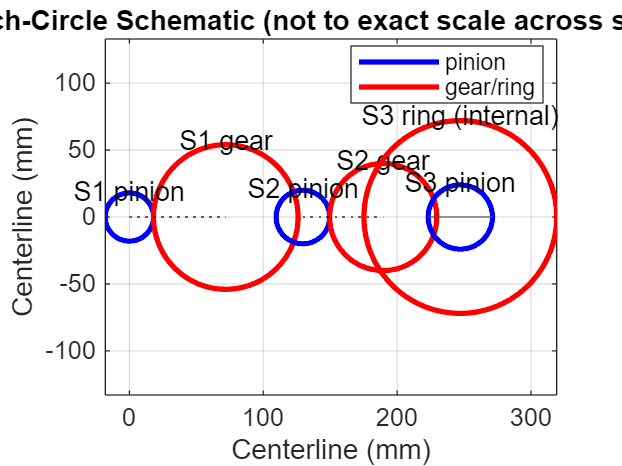


%% ---------------------- PITCH-CIRCLE SCHEMATIC --------------------------
figure('Color','w'); hold on; axis equal; grid on; box on;
title('Pitch-Circle Schematic (not to exact scale across stages)');
xlabel(sprintf('Centerline (%s)',unit_name)); ylabel(sprintf('Centerline (%s)',unit_name));

% Place each stage along x, draw pitch circles
x_cursor = 0; pad = 0.6*max(a_units); if pad==0, pad=10; end
for k = 1:nStages
    if use_module
        Rp = 0.5 * mDP(k) * z_p(k);      % mm
        Rg = 0.5 * mDP(k) * z_g(k);      % mm
    else
        Rp = 0.5 * z_p(k) / mDP(k);      % inch
        Rg = 0.5 * z_g(k) / mDP(k);      % inch
    end
    a  = a_units(k);

    if tcode(k)==0
        % External mesh: separate centers by a
        c1 = [x_cursor, 0];
        c2 = [x_cursor + a, 0];
        drawCircle(c1, Rp, 'b-'); drawCircle(c2, Rg, 'r-');
        plot([c1(1), c2(1)], [0,0], 'k:');    % center distance line
        text(c1(1), Rp*1.05, sprintf('S%d pinion',k), 'HorizontalAlignment','center');
        text(c2(1), Rg*1.05, sprintf('S%d gear',k),   'HorizontalAlignment','center');
        x_cursor = x_cursor + (a + pad);      % advance
    else
        % Internal mesh: pinion inside a ring
        c = [x_cursor, 0];
        drawCircle(c, Rp, 'b-');              % pinion
        drawCircle(c, Rg, 'r-');              % ring
        line([c(1)-Rp, c(1)+Rp],[0,0],'Color',[0.3 0.3 0.3],'LineStyle','-');
        text(c(1), Rg*1.05, sprintf('S%d ring (internal)',k), 'HorizontalAlignment','center');
        text(c(1), Rp*1.05, sprintf('S%d pinion',k), 'HorizontalAlignment','center');
        x_cursor = x_cursor + (max(Rg, a)+ pad);
    end
end
legend({'pinion','gear/ring'},'Location','best');


%% ------------------------- HELPER FUNCTIONS -----------------------------
function drawCircle(c, r, style)
    th = linspace(0, 2*pi, 300);
    plot(c(1) + r*cos(th), c(2) + r*sin(th), style, 'LineWidth', 2);
end
